%% ═══════════════════════════════════════════════════════════════════════════
%% FACE LANDMARK + DROWSINESS (EAR only)
%% Requires: face_detector_merged.onnx
%%           face_landmark_detector_merged.onnx
%% ═══════════════════════════════════════════════════════════════════════════

%% ── STAGE 0 : Load networks ──────────────────────────────────────────────────
detectorNet = importNetworkFromONNX("face_detector_merged.onnx");
landmarkNet = importNetworkFromONNX("face_landmark_detector_merged.onnx");

%% ── STAGE 1 : Load & preprocess for detector (256×256, [-1,1]) ──────────────
img_orig = imread("WIN_20260425_15_33_35_Pro.jpg");
[origH, origW, ~] = size(img_orig);

img256   = imresize(img_orig, [256 256]);
img256   = im2single(img256) * 2 - 1;
detInput = dlarray(img256, "SSCB");

%% ── STAGE 2 : Generate BlazeFace anchors for 256×256 back model ─────────────
% The back (256px) model uses two feature map layers: 16×16 (2 anchors each)
% and 8×8 (6 anchors each) → 512 + 384 = 896 anchors total.
% Each anchor is (cx, cy) in normalised [0,1] image coords.
anchors = generateBlazeFaceAnchors();   % [896, 2]

%% ── STAGE 3 : Run face detector ─────────────────────────────────────────────
[box_coords_1, box_coords_2, box_scores_1, box_scores_2] = predict(detectorNet, detInput);

% sigmoid on dlarray BEFORE extractdata
scores1 = extractdata(sigmoid(box_scores_1));
scores2 = extractdata(sigmoid(box_scores_2));
coords1 = extractdata(box_coords_1);
coords2 = extractdata(box_coords_2);

% Flatten to [896, 1] and [896, 16]
all_scores = [scores1(:); scores2(:)];          % [896, 1]
c1 = reshape(coords1, 512, 16);
c2 = reshape(coords2, 384, 16);
all_coords = [c1; c2];                          % [896, 16]

%% ── STAGE 4 : Decode boxes using anchor centres ──────────────────────────────
% BlazeFace raw output: (dy, dx, dh, dw) as offsets scaled by input size (256)
% Decoded:  cx = anchor_cx + dx/256
%           cy = anchor_cy + dy/256
%           w  = dw / 256
%           h  = dh / 256
SCALE = 256.0;
decoded_cx = anchors(:,1) + all_coords(:,2) / SCALE;
decoded_cy = anchors(:,2) + all_coords(:,1) / SCALE;
decoded_w  = all_coords(:,4) / SCALE;
decoded_h  = all_coords(:,3) / SCALE;

%% ── STAGE 5 : Pick best detection ───────────────────────────────────────────
CONF_THRESH = 0.5;
[best_score, best_idx] = max(all_scores);

if best_score < CONF_THRESH
    figure; imshow(img_orig);
    title("No face detected", 'Color', 'r');
    return;
end
fprintf("Face detected — confidence: %.2f\n", best_score);

Face detected — confidence: 0.83



cx = decoded_cx(best_idx);
cy = decoded_cy(best_idx);
bw = decoded_w(best_idx);
bh = decoded_h(best_idx);

%% ── STAGE 6 : Crop face with padding ────────────────────────────────────────
PAD = 0.25;
x1 = max(0, cx - bw/2 - PAD*bw);
y1 = max(0, cy - bh/2 - PAD*bh);
x2 = min(1, cx + bw/2 + PAD*bw);
y2 = min(1, cy + bh/2 + PAD*bh);

px1 = max(1,     round(x1 * origW));
py1 = max(1,     round(y1 * origH));
px2 = min(origW, round(x2 * origW));
py2 = min(origH, round(y2 * origH));

face_crop = img_orig(py1:py2, px1:px2, :);

%% ── STAGE 7 : Run landmark detector (192×192) ───────────────────────────────
face192 = imresize(face_crop, [192 192]);
face192 = im2single(face192) * 2 - 1;
lmInput = dlarray(face192, "SSCB");

[lm_score, lm_landmarks] = predict(landmarkNet, lmInput);

face_present = extractdata(sigmoid(lm_score));
landmarks    = squeeze(extractdata(lm_landmarks));  % [468, 3]

fprintf("Face presence: %.2f\n", face_present);

Face presence: 0.73



% Map X/Y from crop space [0,192] → original image pixels
lm_x = landmarks(:,1) / 192 * (px2 - px1) + px1;
lm_y = landmarks(:,2) / 192 * (py2 - py1) + py1;

%% ── STAGE 8 : EAR drowsiness ────────────────────────────────────────────────
LEFT_EYE  = [33, 160, 158, 133, 153, 144] + 1;
RIGHT_EYE = [362, 385, 387, 263, 373, 380] + 1;
MOUTH     = [61, 291, 13, 14, 17, 0]      + 1;

left_EAR  = eyeAspectRatio(landmarks, LEFT_EYE);
right_EAR = eyeAspectRatio(landmarks, RIGHT_EYE);
avg_EAR   = (left_EAR + right_EAR) / 2;

EAR_THRESH = 0.21;
if avg_EAR < EAR_THRESH
    status     = "DROWSY";
    titleColor = 'r';
else
    status     = "ALERT";
    titleColor = 'g';
end

fprintf("Left EAR: %.3f  Right EAR: %.3f  Avg: %.3f  → %s\n", ...
    left_EAR, right_EAR, avg_EAR, status);

Left EAR: 0.359  Right EAR: 0.370  Avg: 0.365  → ALERT


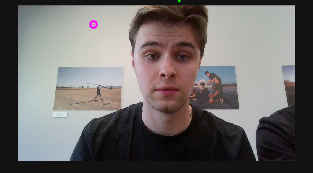


%% ── STAGE 9 : Visualise ──────────────────────────────────────────────────────
figure;
imshow(img_orig); hold on;

% All 468 landmarks — small grey dots
plot(lm_x, lm_y, '.', 'Color', [0.6 0.6 0.6], 'MarkerSize', 2);

% Left eye — cyan
plot(lm_x(LEFT_EYE),  lm_y(LEFT_EYE),  'o', 'Color', 'c', 'MarkerSize', 5, 'LineWidth', 1.5);
plot(lm_x([LEFT_EYE,  LEFT_EYE(1)]),   lm_y([LEFT_EYE,  LEFT_EYE(1)]),  'c-', 'LineWidth', 1.2);

% Right eye — yellow
plot(lm_x(RIGHT_EYE), lm_y(RIGHT_EYE), 'o', 'Color', 'y', 'MarkerSize', 5, 'LineWidth', 1.5);
plot(lm_x([RIGHT_EYE, RIGHT_EYE(1)]),  lm_y([RIGHT_EYE, RIGHT_EYE(1)]), 'y-', 'LineWidth', 1.2);

% Mouth — magenta
plot(lm_x(MOUTH),     lm_y(MOUTH),     'o', 'Color', 'm', 'MarkerSize', 5, 'LineWidth', 1.5);
plot(lm_x([MOUTH,     MOUTH(1)]),      lm_y([MOUTH,     MOUTH(1)]),     'm-', 'LineWidth', 1.2);

title(sprintf('EAR = %.3f  |  %s', avg_EAR, status), ...
    'Color', titleColor, 'FontSize', 14);
hold off;


%% ═══════════════════════════════════════════════════════════════════════════
%% HELPER FUNCTIONS
%% ═══════════════════════════════════════════════════════════════════════════

function anchors = generateBlazeFaceAnchors()
    % BlazeFace back model (256×256 input) anchor grid
    % Layer 1: 16×16 spatial grid, 2 anchors per cell → 512 anchors
    % Layer 2:  8×8  spatial grid, 6 anchors per cell → 384 anchors
    % Total: 896 anchors, stored as normalised (cx, cy) in [0,1]

    anchors = zeros(896, 2, 'single');
    idx = 1;

    % Layer 1 — 16×16 grid, 2 anchors per cell
    for row = 0:15
        for col = 0:15
            for i= 1:2
                anchors(idx, 1) = (col + 0.5) / 16;   % cx
                anchors(idx, 2) = (row + 0.5) / 16;   % cy
                idx = idx + 1;
            end
        end
    end

    % Layer 2 — 8×8 grid, 6 anchors per cell
    for row = 0:7
        for col = 0:7
            for i= 1:6
                anchors(idx, 1) = (col + 0.5) / 8;    % cx
                anchors(idx, 2) = (row + 0.5) / 8;    % cy
                idx = idx + 1;
            end
        end
    end
end

function ear = eyeAspectRatio(lm, indices)
    pts = lm(indices, 1:2);
    A   = norm(pts(2,:) - pts(6,:));
    B   = norm(pts(3,:) - pts(5,:));
    C   = norm(pts(1,:) - pts(4,:));
    ear = (A + B) / (2.0 * C);
end